# PRÁCTICA 6

# Detección de discontinuidades

## OPERADORES BASADOS EN LA PRIMERA DERIVADA

- PREWITT

- SOBEL

### Aplicación del operador SOBEL : (la variable ‘im’ contiene la imagen original)

Generación de máscaras:

Aplicación de máscaras:

Módulo y dirección del vector gradiente:

Mostrar imagen gradiente e imagen de ángulos:

Binarizar imagen:

#### EJERCICIO 1

Cargue y muestre en una figura las imágenes “Disk\disk01.jpg” “Classification\Parts00.png”, “Chocolate\chocolate 01.jpg” y “Geometric Matching\gauges 01.tif” (im1, im2, m3 e im4).

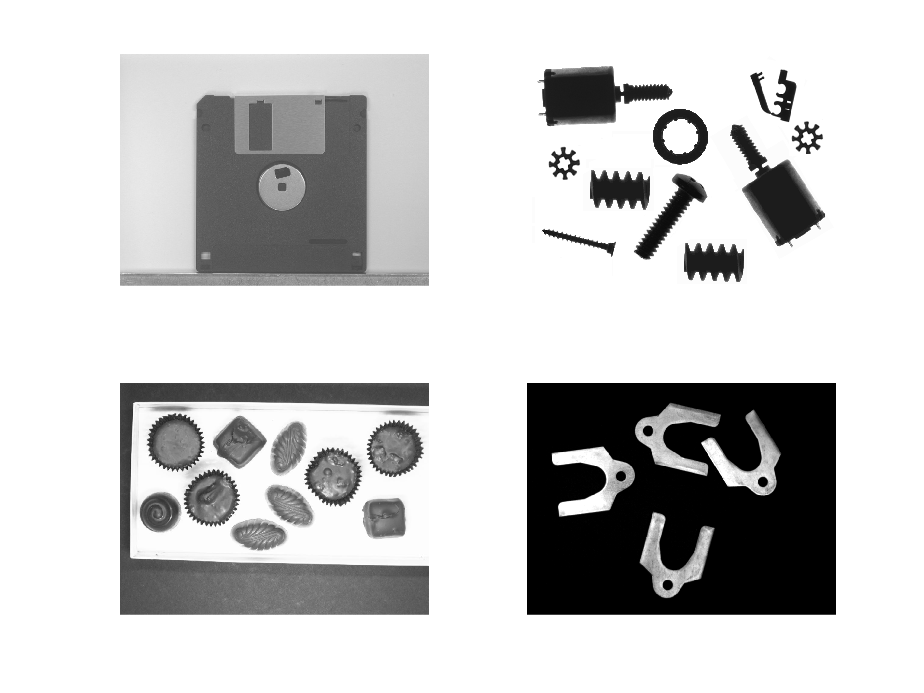

im1 = imread("DISK01.JPG");
im2 = imread("Parts00.png");
im3 = imread("Chocolate 01.jpg");
im4 = imread("Gauges 01.tif");
figure
subplot(2,2,1); imshow(im1);
subplot(2,2,2); imshow(im2);
subplot(2,2,3); imshow(im3);
subplot(2,2,4); imshow(im4);

#### EJERCICIO 2

Obtenga el gradiente SOBEL en las direcciones x e y (im1sx e im1sy) de la imagen im1 y muestre una figura que contenga la imagen original, los gradientes en ambas direcciones (en valor absoluto) y el modulo del vector gradiente (im1s), subplot(2,2,…).

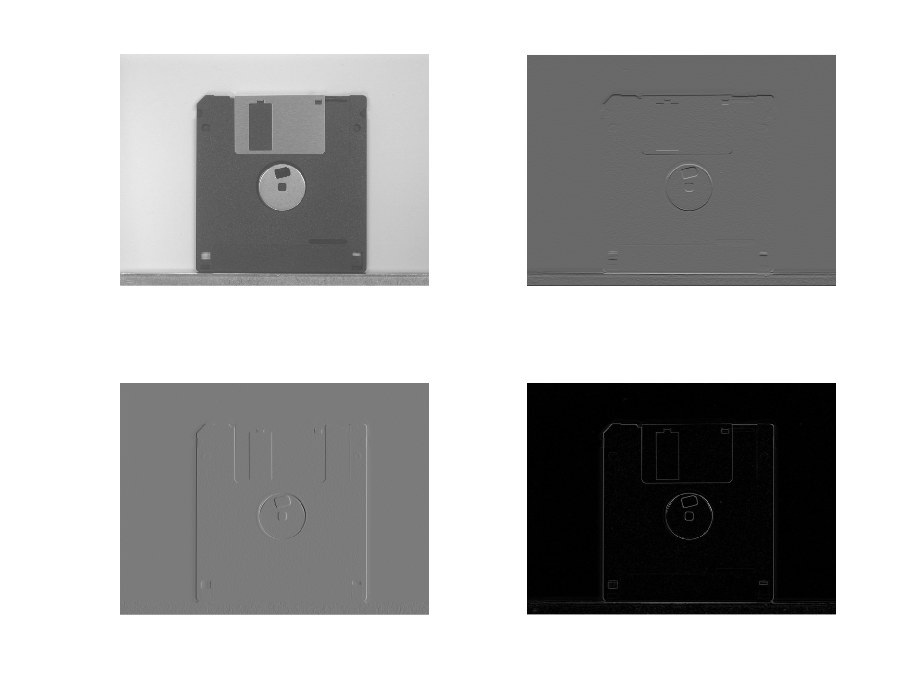

sx = fspecial('sobel'); 
sy = sx';
im1sx = conv2 (im1, sx,'same');
im1sy = conv2 (im1, sy,'same');
im1gr = abs(im1sx) + abs(im1sy);
figure;
subplot(2,2,1); imshow(im1);
subplot(2,2,2); imshow(im1sx, []);
subplot(2,2,3); imshow(im1sy, []);
subplot(2,2,4); imshow(im1gr, []);

#### EJERCICIO 3

Obtenga el gradiente sobel imagen im2 y muestre la imagen original, la imagen gradiente y la dirección del vector gradiente (im2g, im2a). subplot(1,3,…).

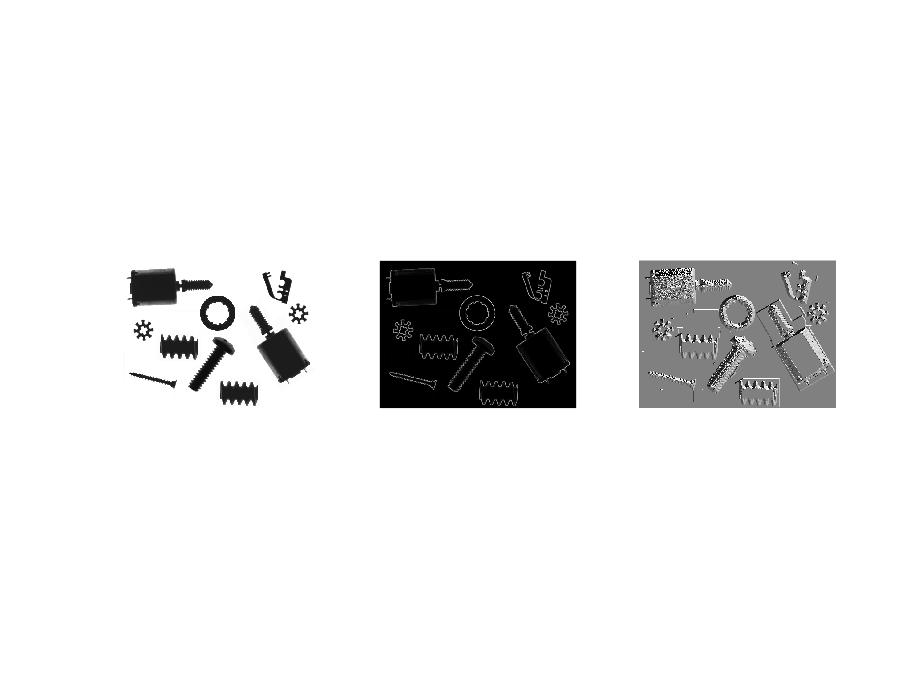

im2sx = conv2 (im2, sx,'same');
im2sy = conv2 (im2, sy,'same');
im2gr = abs(im2sx) + abs(im2sy);
im2an = atan2 (im2sy,im2sx);
figure;
subplot(1,3,1); imshow(im2);
subplot(1,3,2); imshow(im2gr, []);
subplot(1,3,3); imshow((im2an+pi)/(2*pi));

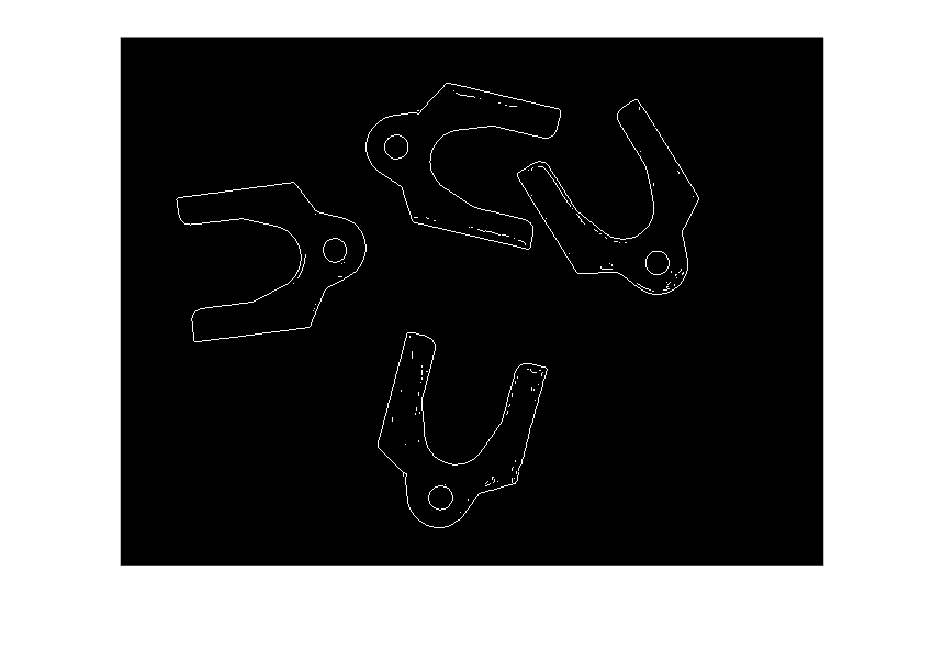

figure;
edge(im4)

#### EJERCICIO 4

Ejecute el siguiente código y analice el resultado.

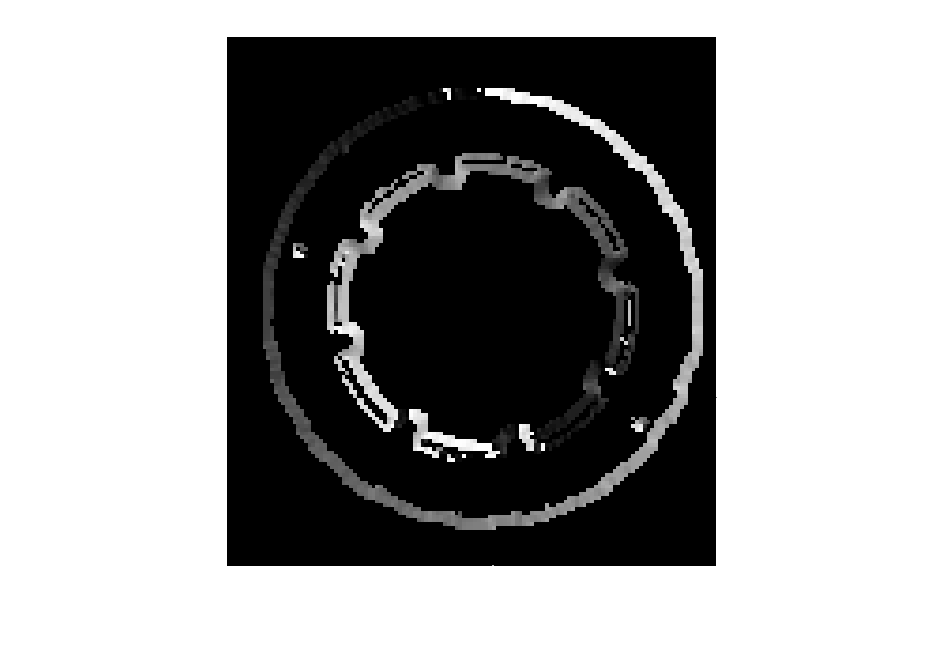

% los ángulos empiezan al norte. El círculo de fuera va de más a
% menos y el de dentro de menos a más.
% nos quedamos con la parte del ángulo cuyo gradiente supera 55
% el sober de matlab deja el ángulo al este
figure, imshow ( ( (im2an+pi) .* (im2gr > 55) ) / (2*pi));
axis ([250 380 100 240]);

#### EJERCICIO 5

Obtenga las imágenes gradientes binarizadas de la imagen im4 empleando las máscaras SOBEL, y umbrales de binarización 0.01, 0.02, 0.05, 0.1 y 0.2. Muestre una figura con im4 y las imágenes binarias, subplot(2,3,…).

NOTA: normalice la imagen gradiente dividiéndola por su valor máximo. max(max(<>))

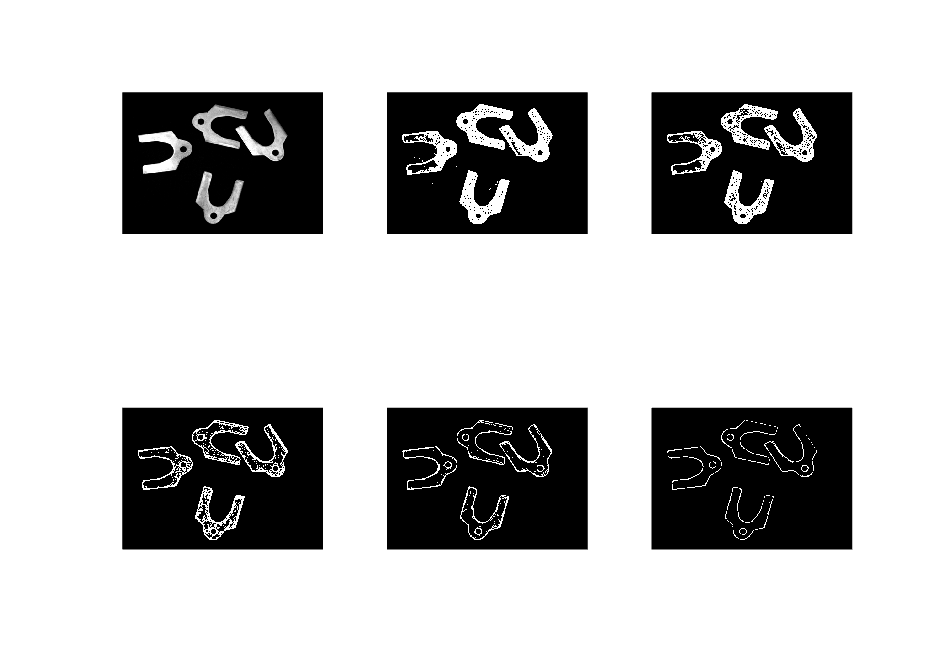

im4sx = conv2 (im4, sx,'same');
im4sy = conv2 (im4, sy,'same');
im4gr = abs(im4sx) + abs(im4sy);
M = max(max(im4gr));
im4Mx = im4gr/M;

figure;
umbrales = [0 0.01 0.02 0.05 0.1 0.2];
figure;
subplot(2,3,1); imshow(im4);
for i=2:6
    subplot(2,3,i);
    %imshow(im4gr .* (im4gr > umbrales(i)) / M);
    imshow(imbinarize(im4Mx, umbrales(i)));
end

## Comando Matlab edge:

NOTAS:

- Si no se le asigna salida se muestra el resultado en una ventana.

- Realiza una detección de discontinuidades junto con binarización y supresión de no máximos.

- La imagen que devuelve es binaria (0-1)

#### EJERCICIO 6

Aplique el comando edge de Matlab a las imágenes im1, im2, im3 e im4, empleando parámetros por defecto. Muestre el resultado en figuras diferentes.

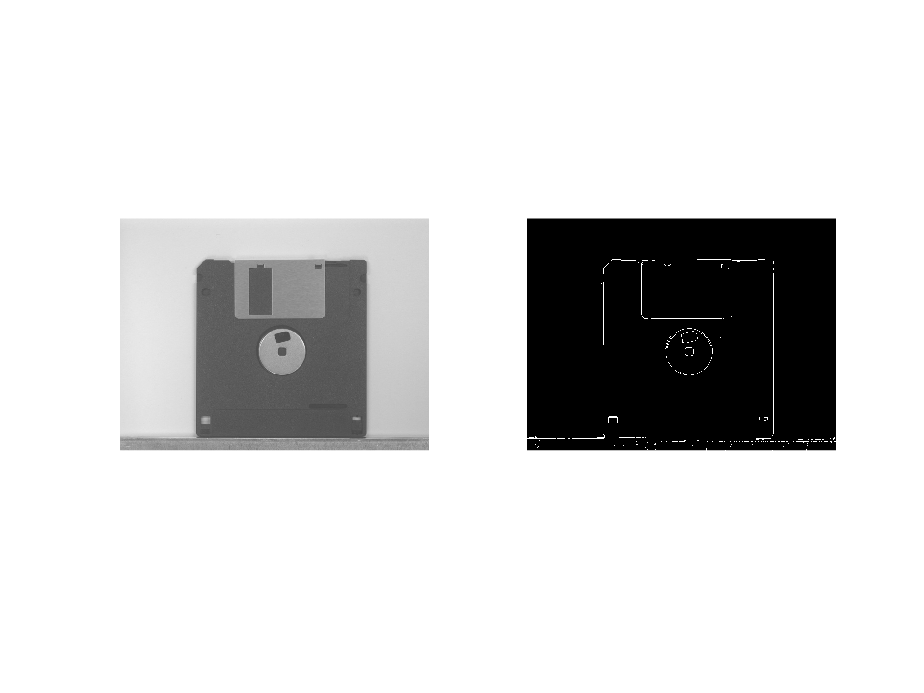

im1ed = edge(im1);
im2ed = edge(im2);
im3ed = edge(im3);
im4ed = edge(im4);

figure
subplot(1,2,1); imshow(im1); 
subplot(1,2,2); imshow(im1ed)

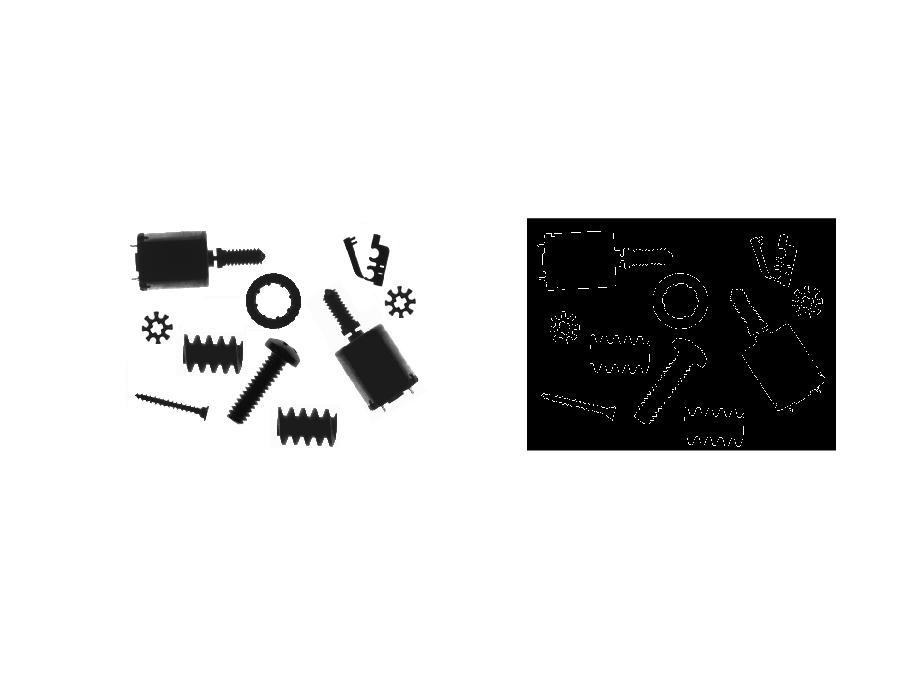

figure
subplot(1,2,1); imshow(im2); 
subplot(1,2,2); imshow(im2ed)

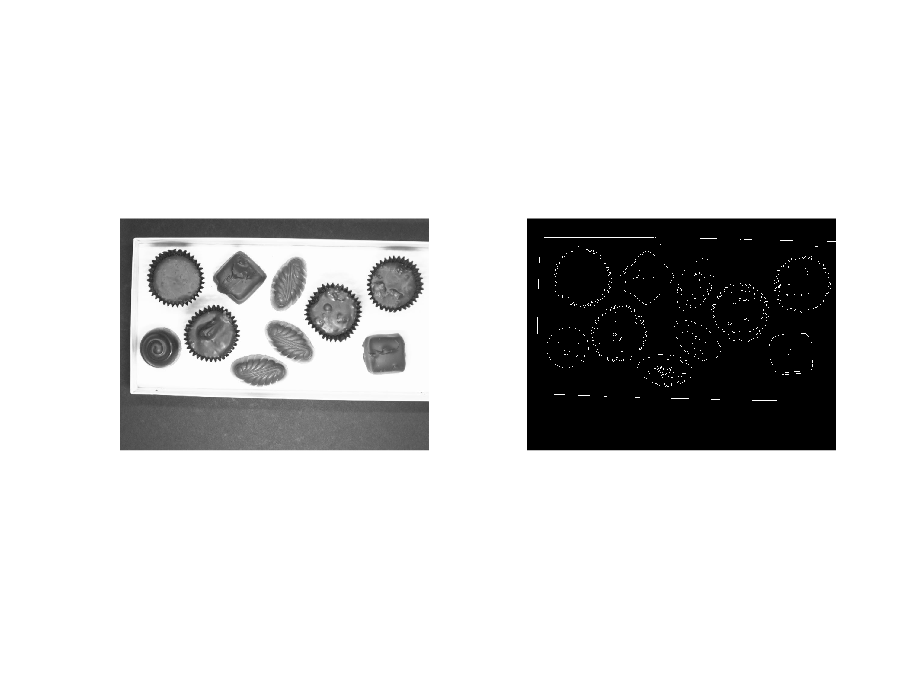


figure
subplot(1,2,1); imshow(im3); 
subplot(1,2,2); imshow(im3ed)

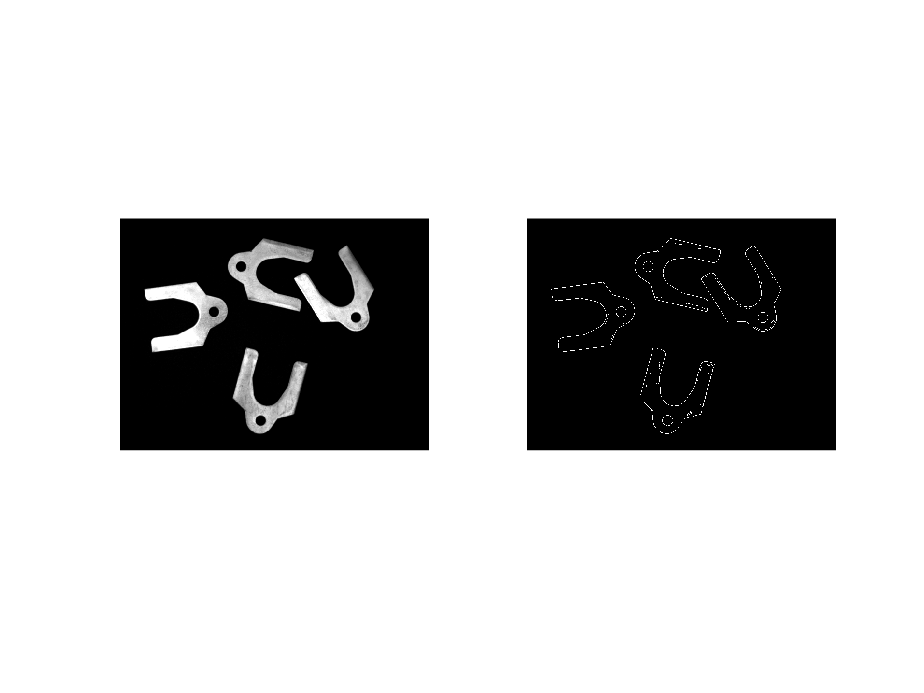


figure
subplot(1,2,1); imshow(im4); 
subplot(1,2,2); imshow(im4ed)

#### EJERCICIO 7

Analice y ejecute el siguiente código.

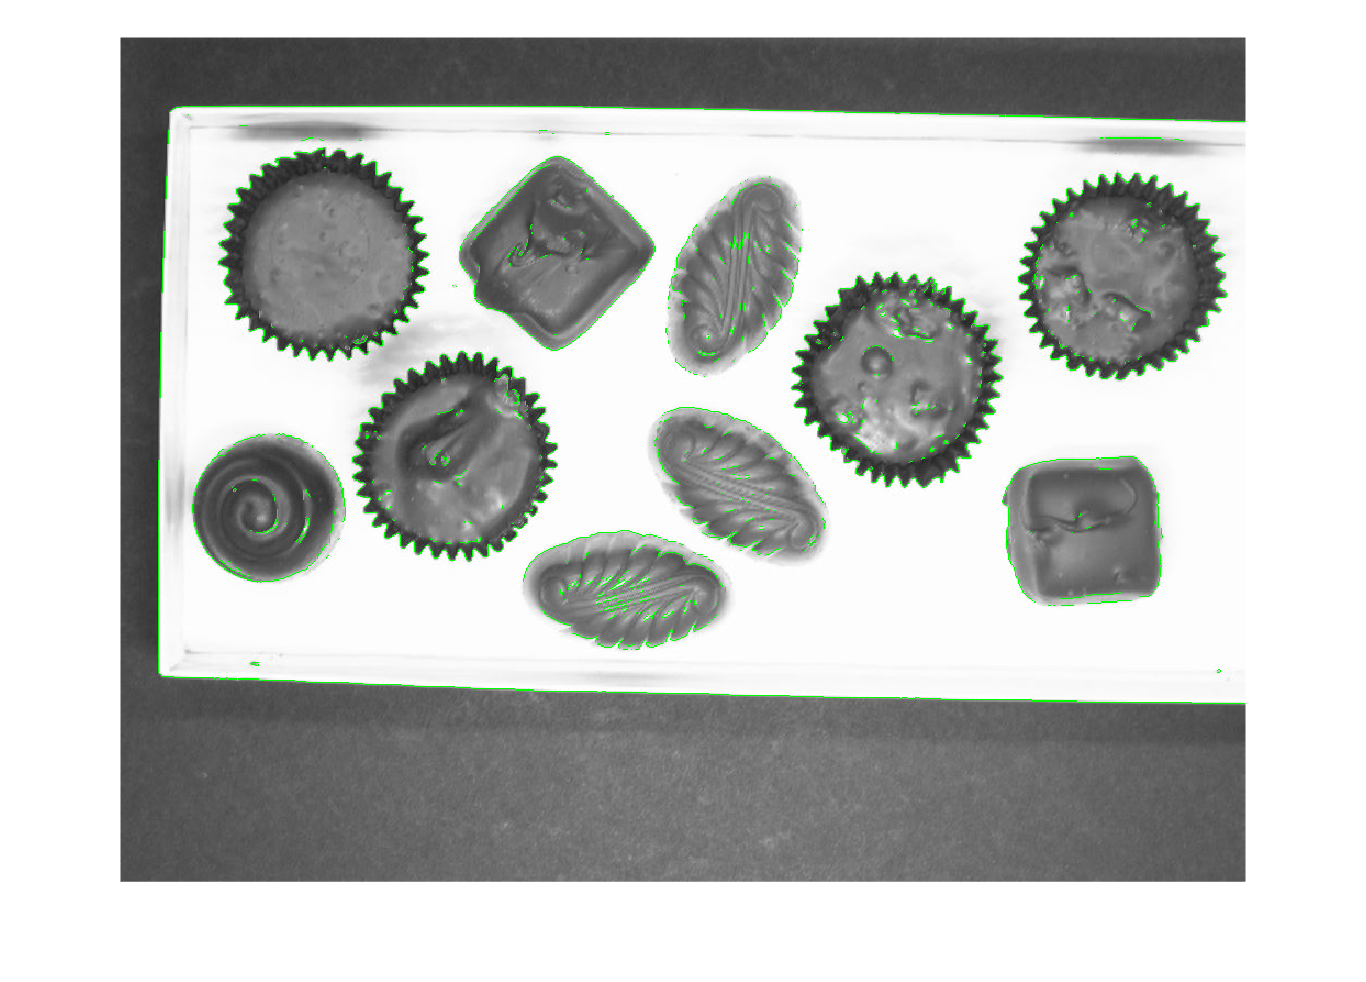

im = double(im3)/255; %imagen a procesar im1,im2,im3 o im4
ime = edge(im);
clear imc; % por si acaso te la has definido, en lugar de clear all
imc(:,:,1) = im.*not(ime); % rojo a cero para los bordes
imc(:,:,2) = im.*not(ime) + ime; % verde para los bordes
imc(:,:,3) = im.*not(ime); % azul
figure, imshow(imc);

## OPERADORES BASADOS EN LA 2ª DERIVADA:

- LAPLACIANA 4 VECINOS 

- LAPLACIANA 8 VECINOS

- MÁSCARA LoG

#### EJERCICIO 8

Cree las máscaras laplaciana 4 vecinos y laplaciana 8 vecinos (L4 y L8).

l4v = [0 -1 0; -1 4 -1;  0 -1 0]

l4v =      0    -1     0
    -1     4    -1
     0    -1     0


l8v = [-1 -1 -1; -1 8 -1; -1 -1 -1]

l8v =     -1    -1    -1
    -1     8    -1
    -1    -1    -1


#### EJERCICIO 9

Cree una máscara LoG de 11x11 con deviación típica 2 y muéstrela como una superficie (L11).

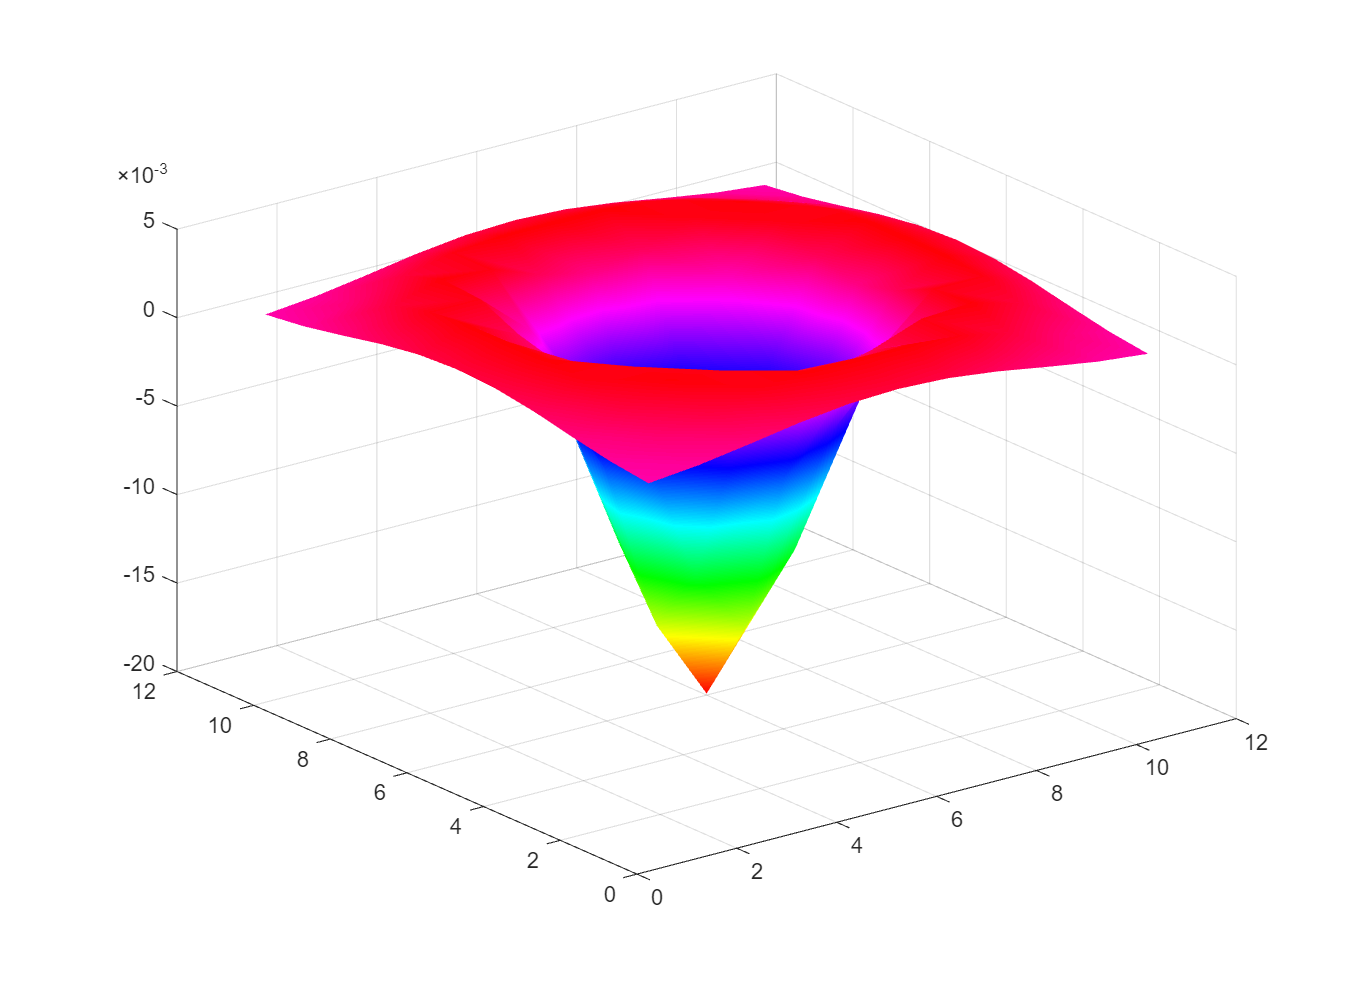

mlog = fspecial('log', 11, 2);
surf(double(mlog));
shading interp;
colormap hsv; % gray;

El siguiente código permite detectar los pasos por cero con cierta amplitud en una imagen:

#### EJERCICIO 10

Realice un programa que tenga como entrada una imagen laplaciana iml y el umbral u y como salida proporcione de la imagen binaria de pasos por cero. (porcero.m)

u = 0.06;
im = im4;
iml = conv2(im, l8v);


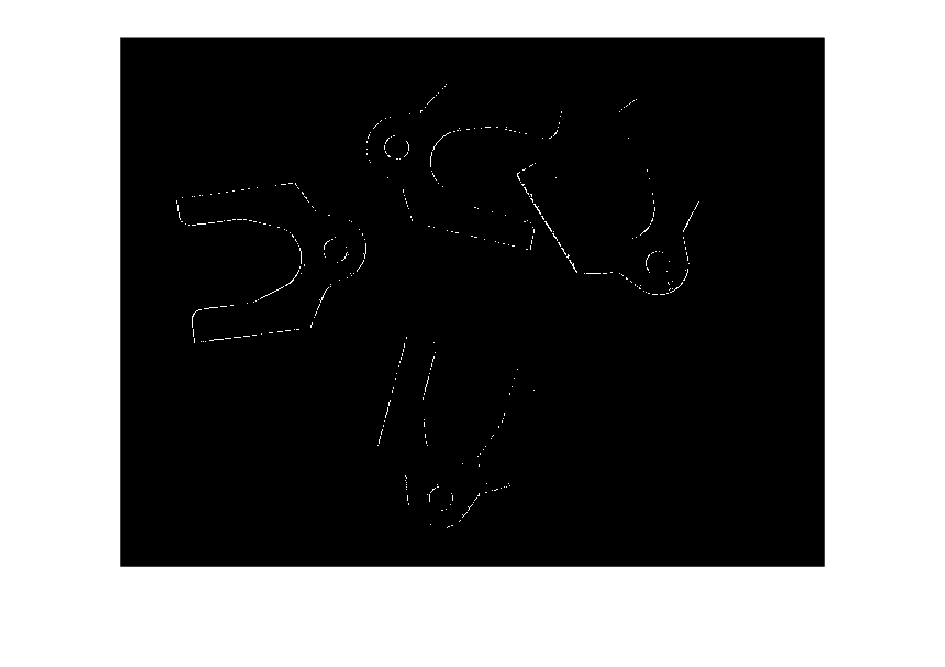

porcero(iml, u)

#### EJERCICIO 11

Aplique L4, L8 y L11 a imagen im2 y muestre en una figura la imagen original, y los pasos por cero de las laplacianas (subplot(2,2,…)).

NOTA: utilice un umbral 0.001 como umbral en la amplitud.

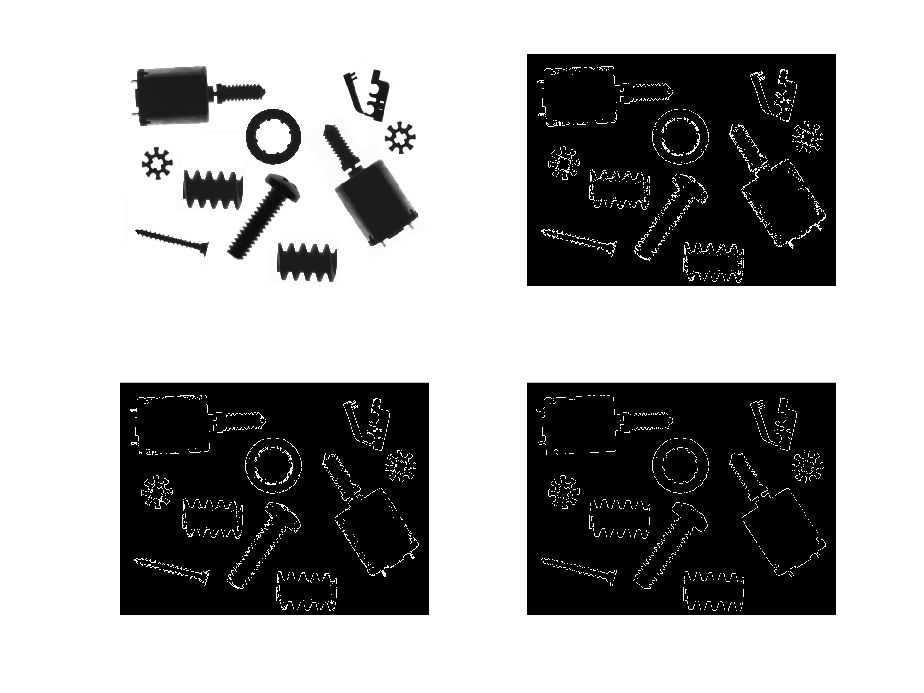

im = im2;
u = 0.001;
iml4v = conv2(im, l4v, 'same');
iml8v = conv2(im, l8v, 'same');
imlog = conv2(im, mlog, 'same');
figure;
subplot(2,2,1); imshow(im);
subplot(2,2,2); porcero(iml4v, u);
subplot(2,2,3); porcero(iml8v, u);
subplot(2,2,4); porcero(imlog, u);

#### EJERCICIO 12

Repita el ejercicio anterior con las imágenes im1, im3 e im4.

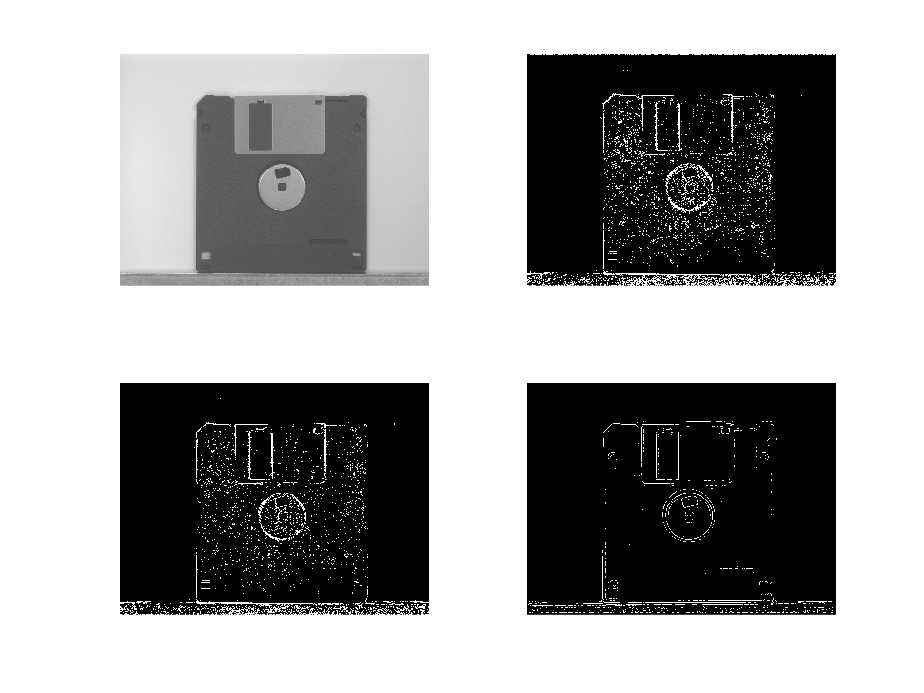

im = im1;
u = 0.001;
iml4v = conv2(im, l4v, 'same');
iml8v = conv2(im, l8v, 'same');
imlog = conv2(im, mlog, 'same');
figure;
subplot(2,2,1); imshow(im);
subplot(2,2,2); porcero(iml4v, u);
subplot(2,2,3); porcero(iml8v, u);
subplot(2,2,4); porcero(imlog, u);

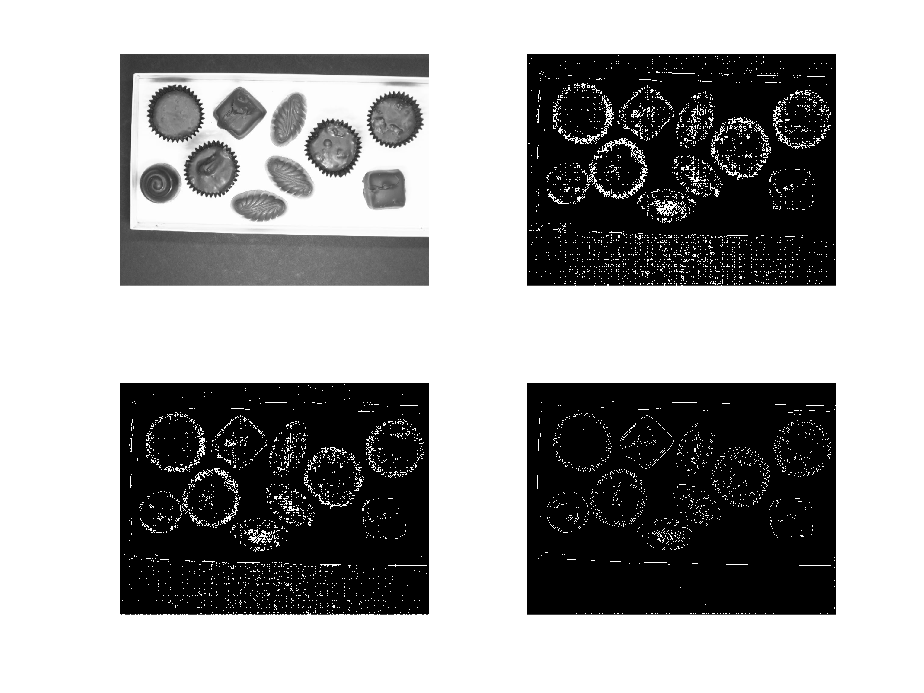


im = im3;
u = 0.001;
iml4v = conv2(im, l4v, 'same');
iml8v = conv2(im, l8v, 'same');
imlog = conv2(im, mlog, 'same');
figure;
subplot(2,2,1); imshow(im);
subplot(2,2,2); porcero(iml4v, u);
subplot(2,2,3); porcero(iml8v, u);
subplot(2,2,4); porcero(imlog, u);

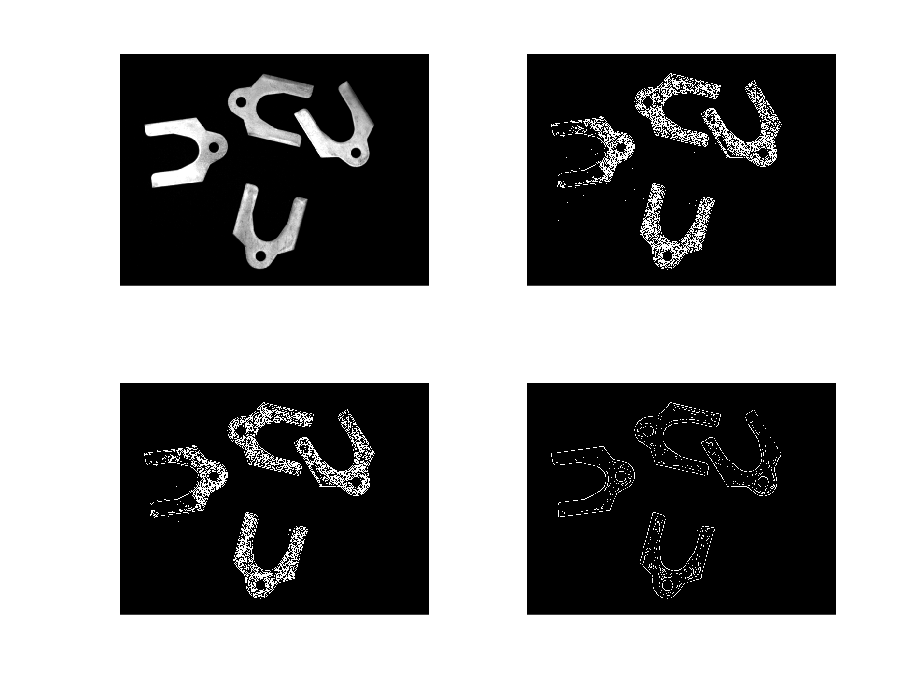


im = im4;
u = 0.001;
iml4v = conv2(im, l4v, 'same');
iml8v = conv2(im, l8v, 'same');
imlog = conv2(im, mlog, 'same');
figure;
subplot(2,2,1); imshow(im);
subplot(2,2,2); porcero(iml4v, u);
subplot(2,2,3); porcero(iml8v, u);
subplot(2,2,4); porcero(imlog, u);

El siguiente código genera la matriz -(2·pi)^2 ·(u^2 + v^2)

#### EJERCICIO 13

Defina la operación laplaciana en el dominio frecuencial H para la imagen im2 y muéstrela utilizando

>> imshow (-H / max (max (-H ) ) )

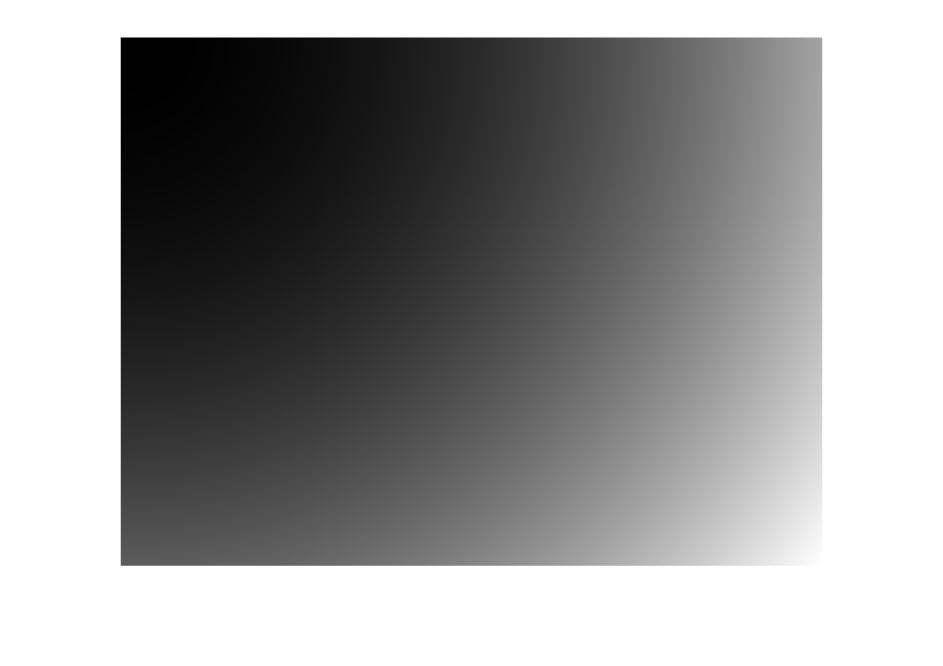

[tamx,tamy] = size(im2);
[uu,vv] = meshgrid(1:tamx,1:tamy);
H = -((2*pi)^2*(uu.^2+vv.^2))';
figure;
imshow(-H / max(max(-H)));

%(ifft2(fft2(im2) .* H))

#### EJERCICIO 14

Aplique la laplacina en el dominio frecuencial a la imagen im2 y muestre los pasos por cero del resultado (umbral 0.00001).

- Laplaciana(F(u,v))= = -(2·pi)^2 (u^2+v^2)·F(u,v)

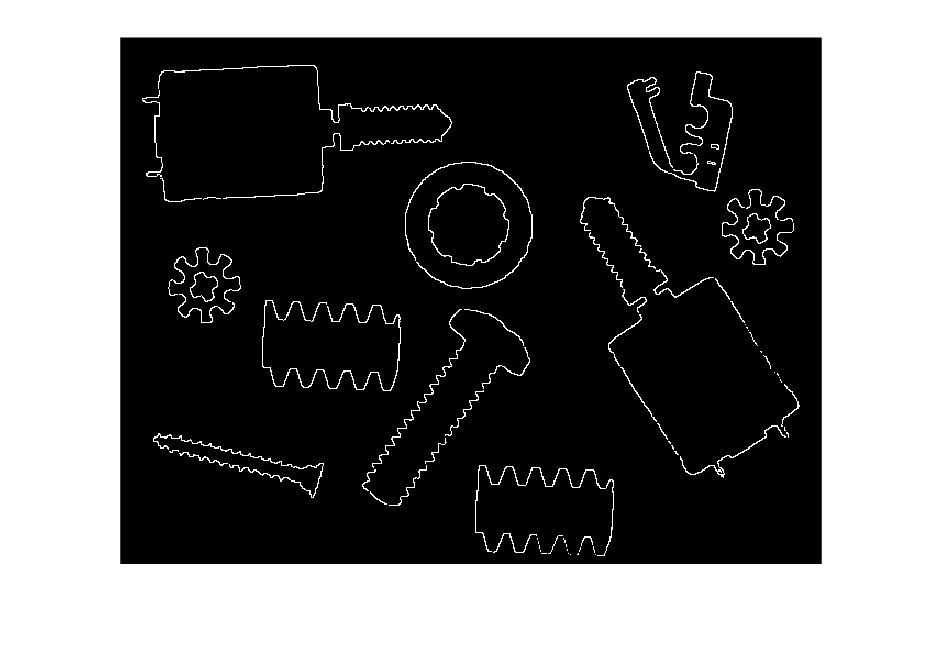

figure;
iml = real(ifft2(fft2(im2) .* H)); % im2 -> fft2(im2) -> multiplico por H -> ifft2 del resultado > parte real
porcero(iml, u);

Repítalo para la imagen im4.

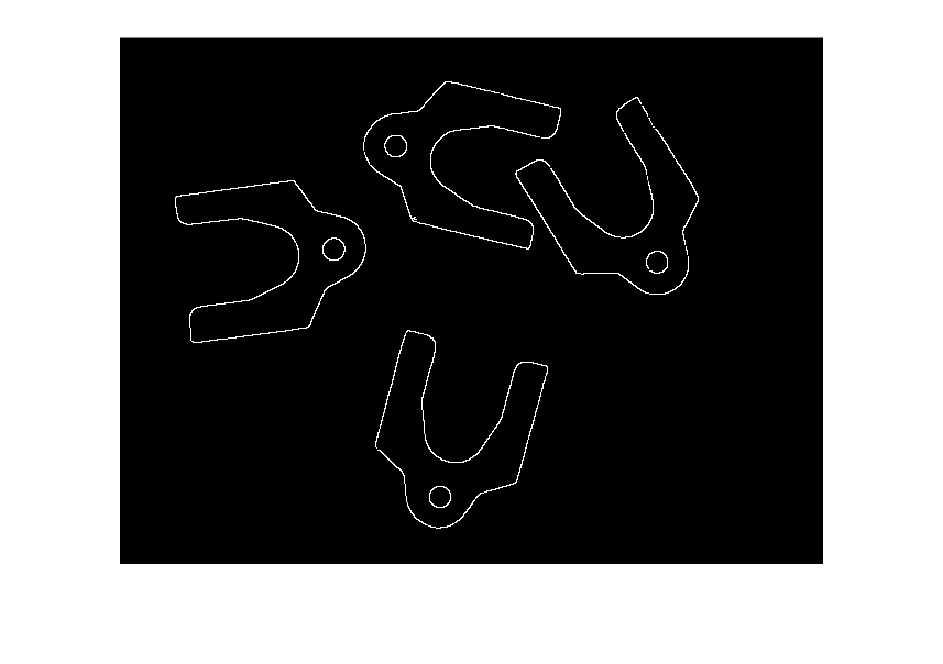

[tamx,tamy] = size(im4);
[uu,vv] = meshgrid(1:tamx,1:tamy);
H = -((2*pi)^2*(uu.^2+vv.^2))';
%figure;
%imshow(-H / max(max(-H)));
figure;
iml = real(ifft2(fft2(im4) .* H)); % im2 -> fft2(im2) -> multiplico por H -> ifft2 del resultado > parte real
porcero(iml, u);

help edge

 edge - Find edges in 2-D grayscale image
    This MATLAB function returns a binary image BW containing 1s where the
    function finds edges in the grayscale or binary image I and 0s
    elsewhere.

    Syntax
      BW = edge(I)
      BW = edge(I,method)
      BW = edge(I,method,threshold)
      BW = edge(I,method,threshold,direction)
      BW = edge(___,"nothinning")
      BW = edge(I,method,threshold,sigma)
      BW = edge(I,method,threshold,h)

      [BW,threshOut] = edge(___)
      [BW,threshOut,Gx,Gy] = edge(___)

    Input Arguments
      I - Input image
        2-D grayscale image | 2-D binary image
      method - Edge detection method
  

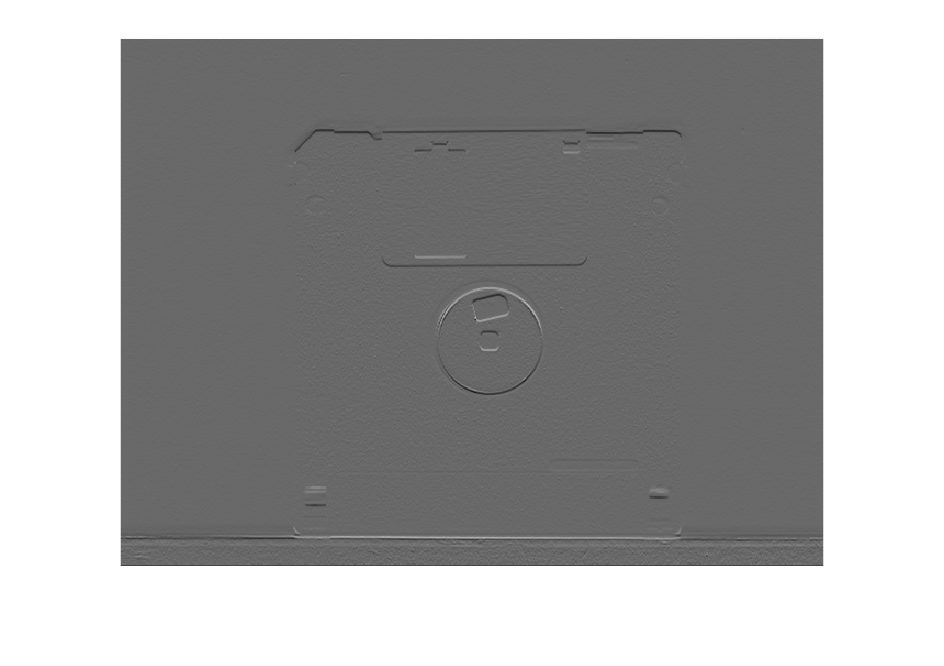

sx = [0 1 0; 0 0 0; 0 -1 0];
sy = sx';
im1sx = conv2 (im1, sx,'same');
im1sy = conv2 (im1, sy,'same');
im1gr = abs(im1sx) + abs(im1sy);
figure;
imshow(im1sx, []);